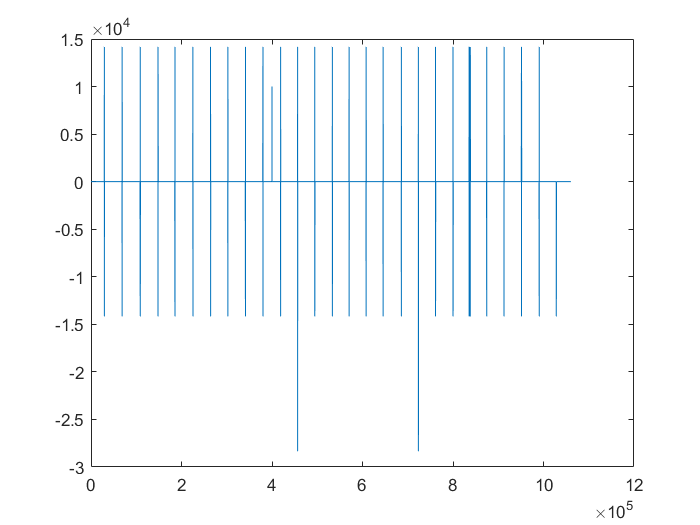

clc; clear all; close all;
[x,fpr] = audioread('DontWorryBeHappy.wav', 'native');
x = double(x);
%soundsc(x,fpr);
a = 0.9545;
Nb = 2; %liczba bitów od 8 brzmi ok od 32 mały błąd
d = x - a*[[0,0]; x(1:end-1,:)];
dq = lab11_kwant(d,Nb);

dq(400000,1) = 10000;
dq(400000,2) = 10000;
figure
plot(dq(:,1))

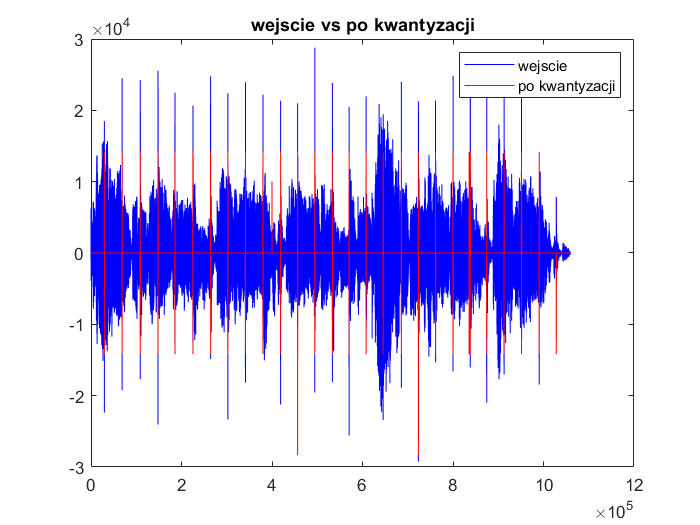

%dekoder
yd=[];
for k=1:2
   dq1 = dq(:,k);
   y(1) = dq1(1);
   for n=2:length(dq)
      y(n) = dq1(n) + a*y(n-1);  
   end
   yd(:,k) = y;
end

%kwantyzacja
figure;
n=1:length(x);
plot(n,x(:,1),'b');
hold on;
plot(n,dq(:,1),'r');
legend("wejscie","po kwantyzacji");
title("wejscie vs po kwantyzacji");

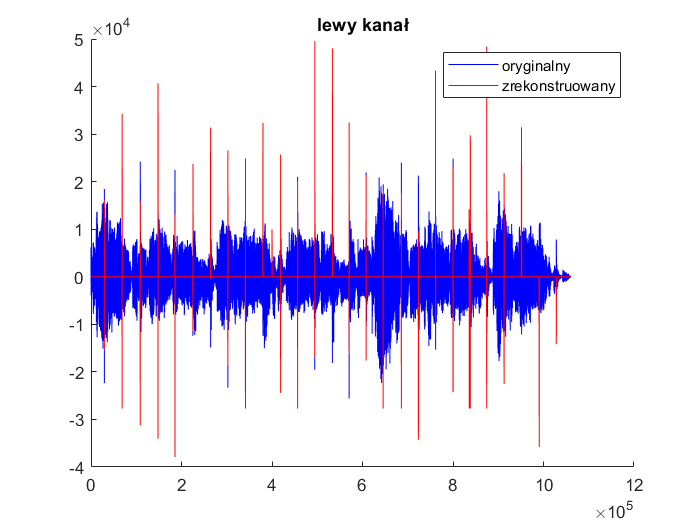


% porównanie sygnałów
figure;
hold on;
plot(x(:,1),'b');
plot(yd(:,1),'r')
legend("oryginalny","zrekonstruowany");
title('lewy kanał')

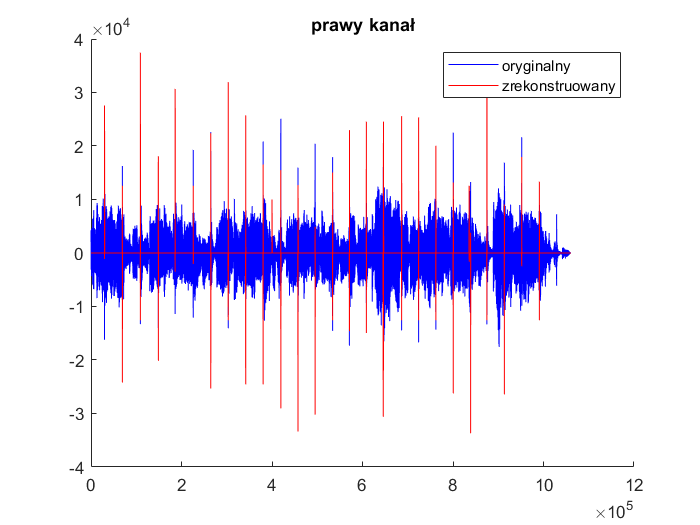


figure;
hold on;
plot(x(:,2),'b');
plot(yd(:,2),'r')
legend("oryginalny","zrekonstruowany");
title('prawy kanał')

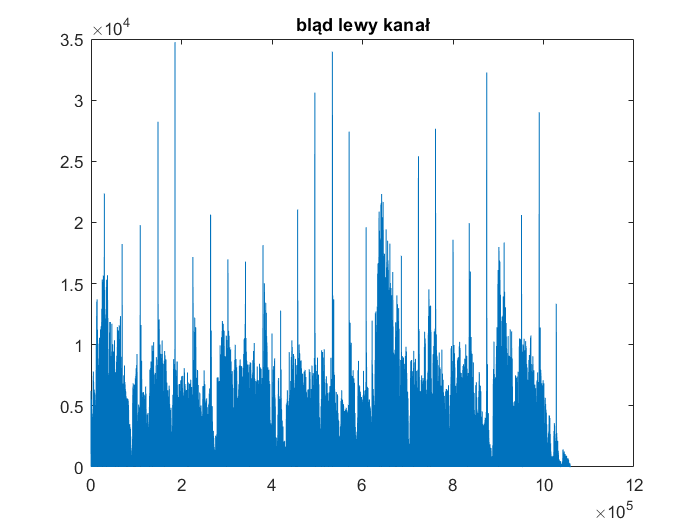

%soundsc(yd,fpr);


figure;
plot(abs(x(:,1)-yd(:,1)));
title('bląd lewy kanał');